# Training a RL Agent for the Dice Game

Environment definition

d = [1 1 1 5 5 8;2 2 3 3 6 6;1 4 4 4 5 7;2 2 6 6 7 8;3 4 5 7 8 8];
states = 0:20;
choices = 1:5;

obsInfo = rlFiniteSetSpec(states);
actInfo = rlFiniteSetSpec(choices);

slEnv = rlSimulinkEnv("targetDice","targetDice/RL die chooser",obsInfo,actInfo);
slEnv.ResetFcn = @randomstart ;

Creating the neural network and visualizing it

obspath = [featureInputLayer(1,"Name","obs");
    fullyConnectedLayer(25,"Name","hiddenobs");
    reluLayer("Name","reluobs");
    fullyConnectedLayer(25,"Name","fcobs")];

actpath = [featureInputLayer(1,"Name","act");
    fullyConnectedLayer(25,"Name","hiddenact");
    reluLayer("Name","reluact");
    fullyConnectedLayer(25,"Name","fcact")];

joinedpath = [additionLayer(2,"Name","add");
    reluLayer("Name","relu");
    fullyConnectedLayer(1,"Name","fc")];

net = layerGraph(obspath)

net =   LayerGraph with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
    Connections: [3×2 table]
     InputNames: {'obs'}
    OutputNames: {1×0 cell}


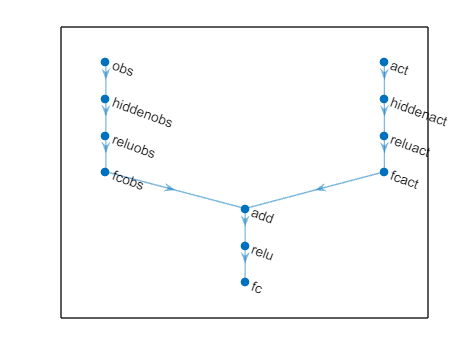


net = addLayers(net,actpath);
net = addLayers(net,joinedpath);
net = connectLayers(net,"fcobs","add/in1");
net = connectLayers(net,"fcact","add/in2");
plot(net)

Create the Q Table critic from the neural network and visualizing it

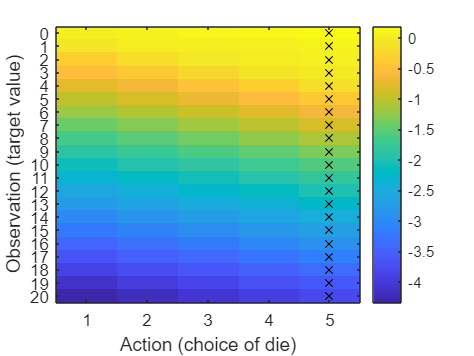

repopts = rlRepresentationOptions("LearnRate",0.008,"GradientThreshold",1);
critic = rlQValueRepresentation(net,obsInfo,actInfo,"Observation","obs","Action","act",repopts);
visualizeQ(critic)

Define the training, simulation and agent options

trainopts = rlTrainingOptions("MaxEpisodes",1000,"MaxStepsPerEpisode",20) ;
trainopts.ScoreAveragingWindowLength = 100 ;
trainopts.StopTrainingCriteria = "AverageReward";
trainopts.StopTrainingValue = -3 ;

simopts = rlSimulationOptions("MaxSteps",30,"NumSimulations",10);

agentopts = rlDQNAgentOptions("DiscountFactor",1)

agentopts =   rlDQNAgentOptions with properties:

                           UseDoubleDQN: 1
               EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                 CriticOptimizerOptions: [1×1 rl.option.rlOptimizerOptions]
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
    ResetExperienceBufferBeforeTraining: 1
                         SequenceLength: 1
                          MiniBatchSize: 64
                    NumStepsToLookAhead: 1
                 ExperienceBufferLength: 10000
                             SampleTime: 1
                         DiscountFactor: 1
                             InfoToSave: [1×1 struct]


Creating and training the agent

agent = rlDQNAgent(critic, agentopts);
info = train(agent,slEnv,trainopts);
save("agentdqna.mat","agent")


Simulating and calculating the average steps

[n,win] = playdice(agent,slEnv,simopts,d)

Target(1)  Die(1)      Sides(6)        Roll(1)
      4      3      1  4  4  4  5  7      3
      1      1      1  1  1  5  5  8      8
      7      4      2  2  6  6  7  8      6
      1      1      1  1  1  5  5  8      1
      0      0      0  0  0  0  0  0      0
Target reached in 4 steps
Target(1)  Die(1)      Sides(6)        Roll(1)
      12      4      2  2  6  6  7  8      6
       6      4      2  2  6  6  7  8      2
       4      3      1  4  4  4  5  7      1
       3      2      2  2  3  3  6  6      3
       0      0      0  0  0  0  0  0      0
Target reached in 4 steps
Target(1)  Die(1)      Sides(6)        Roll(1)
      1      1      1  1  1  5  5  8      8
      7      4      2  2  6  6  7  8      6
      1      1      1  1  1  5  5  8      1
      0      0      0  0  0  0  0  0      0
Target reached in 3 steps
Target(1)  Die(1)      Sides(6)        Roll(1)
      9      4      2  2  6  6  7  8      6
      3      2      2  2  3  3  6  6      2
      1      1      1  1 

n =      4
     4
     3
     7
     2
     3
     2
     9
     4
     6


win =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



averageSteps = 0;
for i = 1:10 
    averageSteps = averageSteps + n(i);
end
averageSteps = averageSteps / 10;
averageSteps

averageSteps = 4.4000